clear all
close all

addpath("C:\Users\simon\Desktop\Imaging Ottico\Immagini\05_slantedEdge")

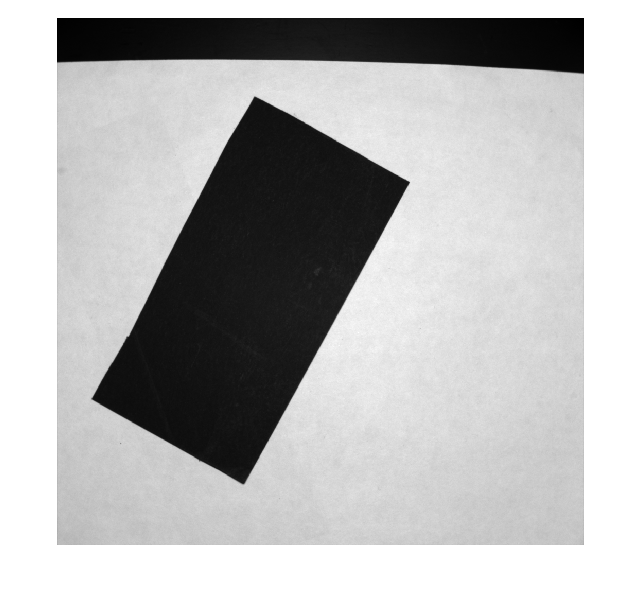

image = imread("T-65-1MHz-1-Conv-2s-B1-slanted.tif");
dark = imread("T-65-1MHz-1-Conv-2s-B1-dark.tif");

SE = image-dark;

imshow(SE,[])

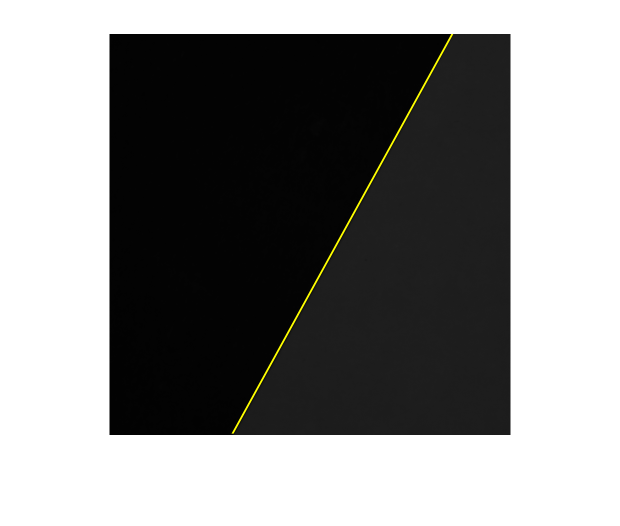

SE = SE(400:800, 300:700);
pos_1 =  [124 401; 344 1];
edge = insertShape(SE, 'line', pos_1, 'Color', 'yellow', 'LineWidth', 3);

imshow(edge, [])


x_m = mean(pos_1(:,1));
y_m = mean(pos_1(:,2));

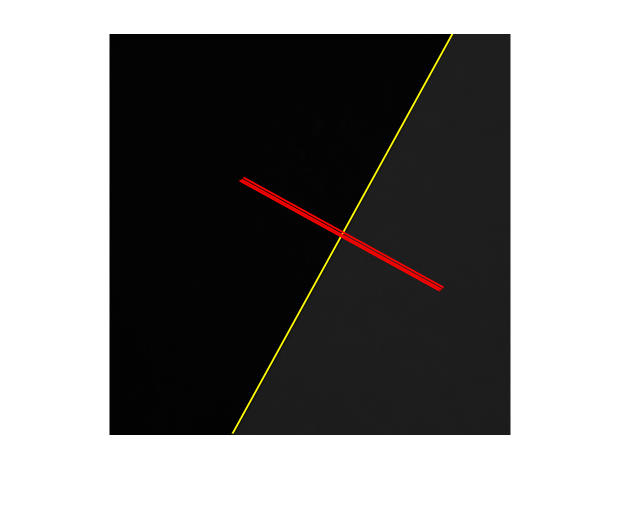

slope = abs(pos_1(1,2) - pos_1(2,2))/abs(pos_1(1,1) - pos_1(2,1));
slope = -1/slope;

y = @(x) slope*(x-x_m) + y_m;

pos_2 = [135 round(y(335)); 335 round(y(135))];
perp_line_1 = insertShape(edge, 'line', pos_2, 'Color', 'red', 'LineWidth', 3);
pos_3 = [133 round(y(333)); 333 round(y(133))];
perp_line_2 = insertShape(perp_line_1, 'line', pos_3, 'Color', 'red', 'LineWidth', 3);
pos_4 = [131 round(y(331)); 331 round(y(131))];
perp_line_3 = insertShape(perp_line_2, 'line', pos_4, 'Color', 'red', 'LineWidth', 3);

imshow(perp_line_3)

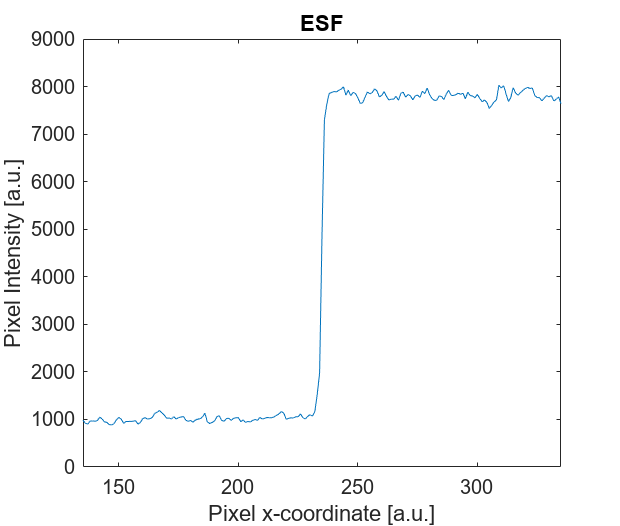

[x_p, y_p, ESF] = improfile(SE, pos_2(:,1), pos_2(:,2));


plot(x_p, ESF)
title("ESF")
ylabel("Pixel Intensity [a.u.]")
xlabel("Pixel x-coordinate [a.u.]")
xlim([x_p(1) x_p(end)])

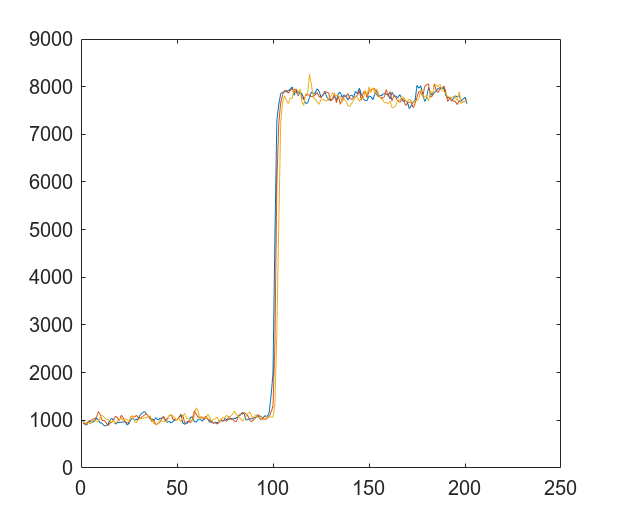

ESF_1 = improfile(SE, pos_2(:,1), pos_2(:,2));
ESF_2 = improfile(SE, pos_3(:,1), pos_3(:,2));
ESF_3 = improfile(SE, pos_4(:,1), pos_4(:,2));
x = 1:length(ESF_3);

plot(x,ESF_1,x,ESF_2,x,ESF_3)

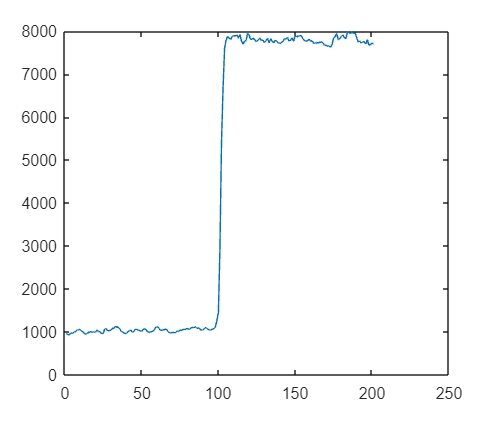


ESF = [ESF_1.'; ESF_2.'; ESF_3.'];
ESF = mean(ESF);

plot(x,ESF)

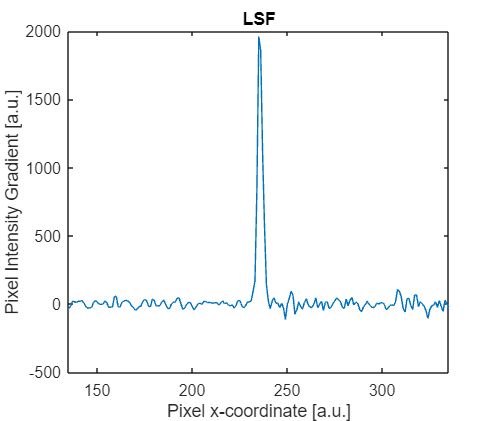

LSF = gradient(ESF);

plot(x_p, LSF)
title("LSF")
ylabel("Pixel Intensity Gradient [a.u.]")
xlabel("Pixel x-coordinate [a.u.]")
xlim([x_p(1) x_p(end)])

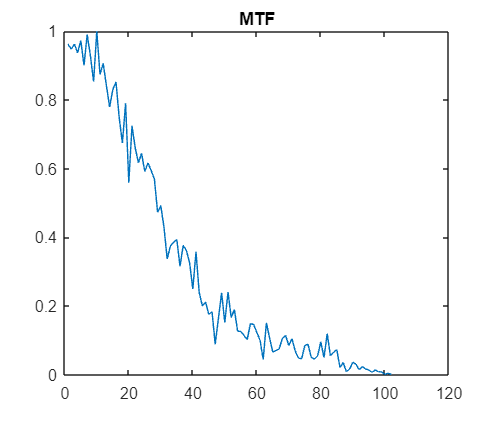

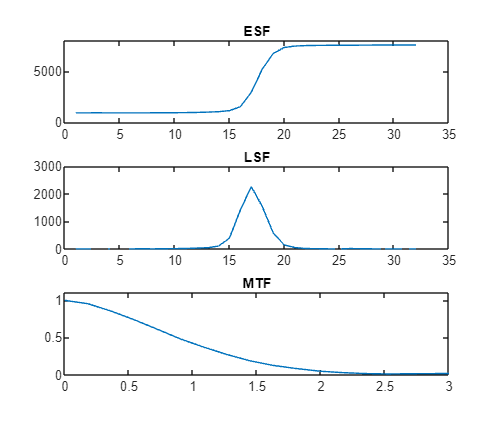

MTF = abs(fftshift(fft(LSF)));
MTF = MTF(100:201)/max(MTF);

plot(MTF)
title("MTF")